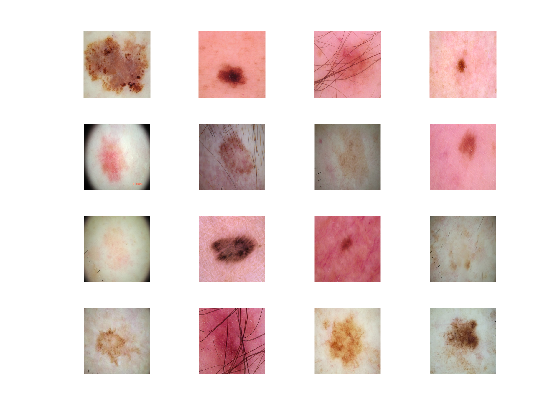

imds= imageDatastore('E:/LICENTA/BD_Skin_Cancer_Screening/mini_data/train/', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames' );
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7, 'randomized');
numTrainImages= numel(imdsTrain.Labels);
idx= randperm(numTrainImages, 16);
figure
for i= 1:16
    subplot(4,4,i)
    I= readimage(imdsTrain, idx(i));
    imshow(I)
end

net= resnet50

net =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}



imputSize= net.Layers(1).InputSize

imputSize =    224   224     3


lgraph= layerGraph(net);
numClasses= 2;
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
    
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer); 
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(imputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(imputSize(1:2),imdsValidation);
options = trainingOptions('rmsprop', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',2, ...
    'Verbose',false, ...
    'Plots','training-progress');
netTransfer = trainNetwork(augimdsTrain,lgraph,options);
save mini_date2.mat netTransfer lgraph 

